# Mess- und Regelungstechnik - Praktikum 4

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Aufgabe 1

Es wird wieder das Szenario des letzten Praktikums betrachtet.

### 1)

Messen Sie mit der gegebenen Funktion `measure` für Distanzen von 10m bis 70m in einem Abstand von 10m jeweils 100 Messwerte.

*Hinweis: Sie können der Funktion einen Vektor an Abständen übergeben. Dann werden mehrere Messungen hintereinander durchgeführt, und die Messwerte in einer Matrix zurückgegeben. Mit einem dritten, optionalen Parameter *`false`* kann die Visualisierung deaktiviert werden.*

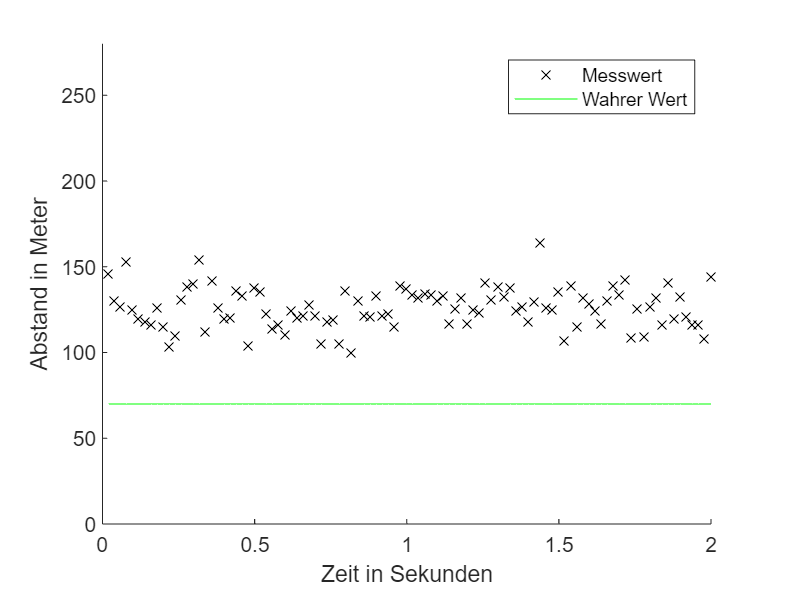

dist = 10:10:70; %horizontal vektor
samples = measure(100, dist, false);

### 2)

Berechnen Sie für jede Distanz (Spalten in der Matrix) den Mittelwert aus den Messwerten. Plotten Sie diese Werte mit einem x-Marker.

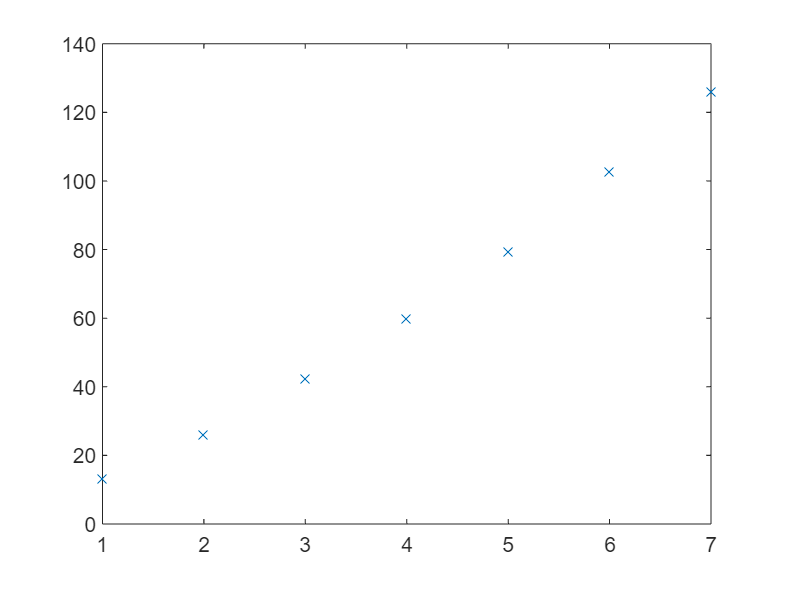

means = mean(samples);
plot(means, 'x');
hold on;

### 3)

Führen Sie eine Polynomapproximation durch, indem Sie die Koeffizienten für ein Polynom 3. Grades erstellen, das sich den Messwerten am besten anpasst. Nutzen Sie hierzu `polyfit`.

koeff = polyfit(dist, means, 3);

### 4)

Erstellen Sie nun die zugehörigen Werte mit `polyval` und plotten Sie diese Werte zusammen mit den in **2)** angezeigten Mittelwerten.

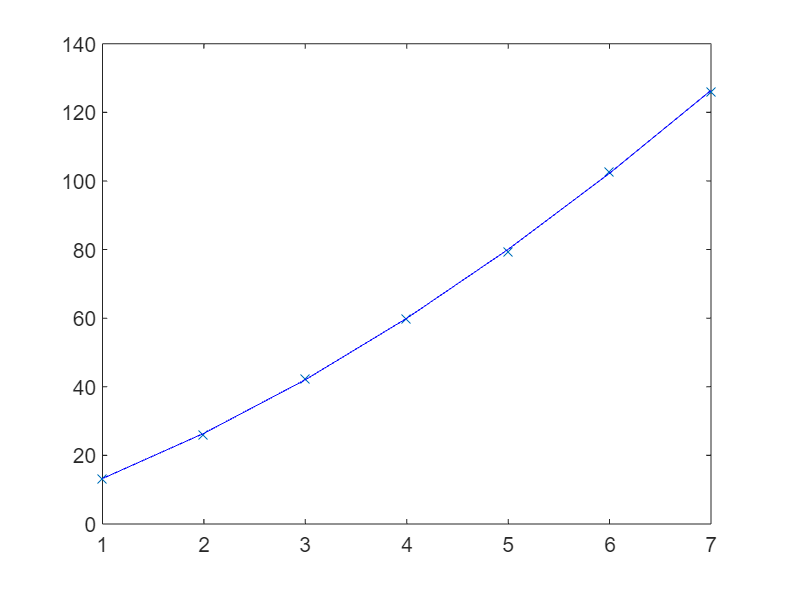

func = polyval(koeff, dist);
plot(func, 'blue');

### 5)

Führen Sie die letzten beiden Schritte für vertauschte Ein- und Ausgangswerte durch. Verwenden Sie hier die Farbe Rot.

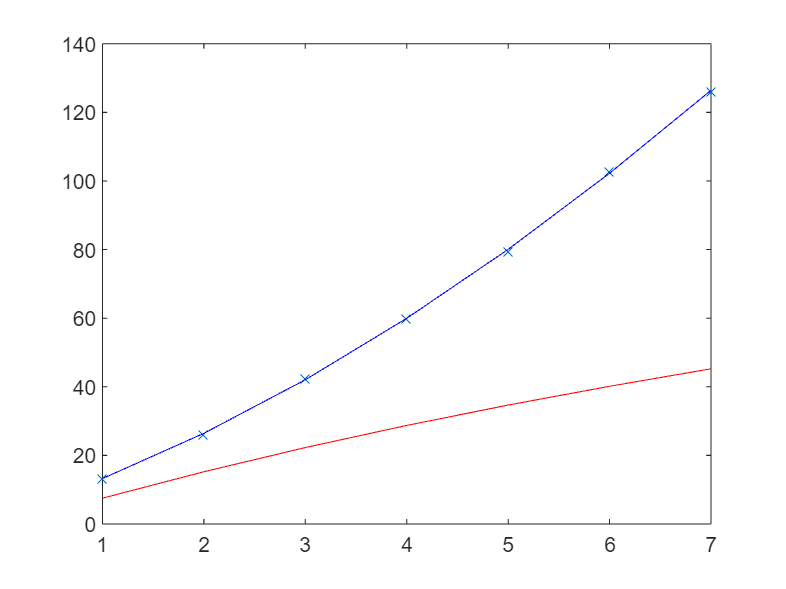

% Was bedeutet hier die Vertauschung der Werte. Ist x = dist oder x = 1:7. Inverses funktioniert mit
% 10-70, aber nicht mit 1-7.
koeffInvert = polyfit(means, dist, 3);
funcInvert = polyval(koeffInvert, dist);

plot(funcInvert, 'red');

### 6)

Nutzen Sie nun `polyval` mit den Koeffizienten aus **5)** und den gemessenen Mittelwerten, um die korrigierten Mittelwerte zu erhalten. Plotten Sie diese Werte in grün.

% Warum gleicht z etwa dist? Was sind hier die korrigierten Mittelwerte?
z = polyval(koeffInvert, means);
disp(z);

   10.1090   19.6869   30.2851   40.0280   49.7956   60.1211   69.9744



disp(func);

   13.2438   26.4331   42.0424   59.9587   80.0685  102.2586  126.4158



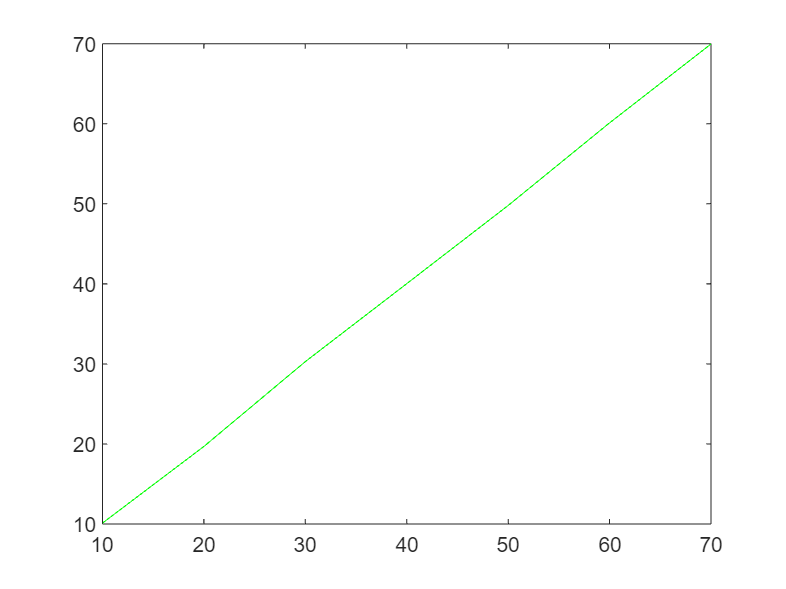

y = polyval(koeffInvert, means);
plot(dist, y, 'green');

### `7)`

Beschriften Sie alle Achsen, betiteln Sie die Grafik und legen Sie eine Legende an.

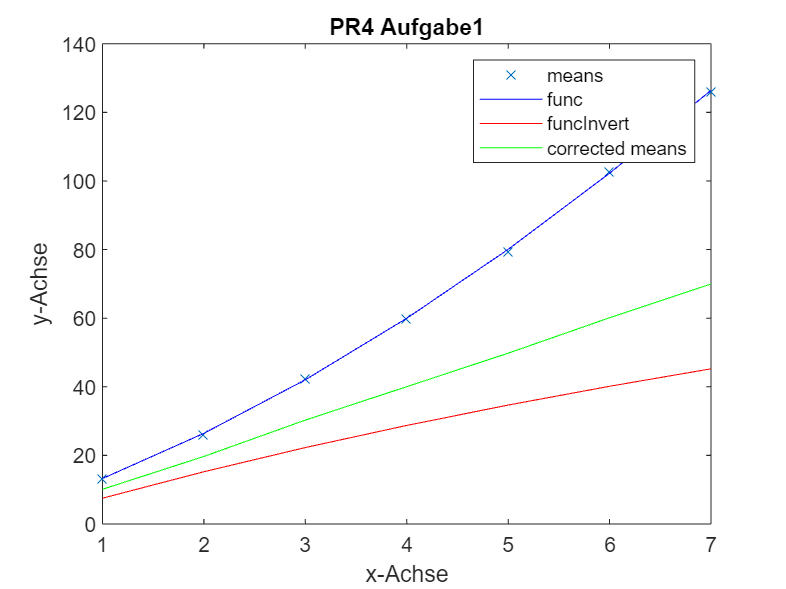

% Create title
title("PR4 Aufgabe1");

% Create ylabel
ylabel({'y-Achse'});

% Create xlabel
xlabel({'x-Achse'});

% Create legend
legend("means", "func", "funcInvert", "corrected means");
hold off;

## Aufgabe 2

Ein Fahrzeug startet an der Position $s_0$ und bewegt sich mit konstanter Geschwindigkeit $v_0$. Diese gleichförmige Bewegung lässt sich durch $y(t) = v_0 \cdot t + x_0$ beschreiben, wobei $y(t)$ die Position des Autos zum Zeitpunkt $t$ angibt.

Für $n$ Wertepaare $\{(t_1, y_1), (t_2, y_2), \dots , (t_n, y_n)\}$ kann zu dieser Gleichung das zugehörige lineare Gleichungssystem als Matrix-Vektor-Produkt dargestellt werden:


$$\begin{array}{c}
y & = & A & \cdot & x \\ \\
\left\lbrack \matrix{
y_1 \cr
y_2 \cr
\vdots \cr
y_n \cr
}\right\rbrack
& = &
\left\lbrack \matrix{
(t_1)^1 & (t_1)^0 \cr
(t_2)^1 & (t_2)^0 \cr
\vdots & \vdots \cr
(t_n)^1 & (t_n)^0 \cr
}\right\rbrack
& \cdot &
\left\lbrack \matrix{
v_0 \cr
s_0 \cr
}\right\rbrack
\end{array}$$


Es existiert ein idealer Sensor, mit dem die Position $y(t)$ exakt gemessen werden kann. Mit diesem Sensor werden zu bestimmten Zeitpunkten Messungen aufgenommen:

values = [4 20; 4 20];
t = values(:, 1)

t =      4
     4


y = values(:, 2)

y =     20
    20


A = [ t ones(length(values), 1) ]

A =      4     1
     4     1


### 1)

Plotten Sie die Werte in einer Grafik mit x-Markern. Wählen Sie in der Choicebox andere Wertepaare aus. Überlegen Sie, wie Sie die Punkte im Plot mit einer Gerade interpolieren bzw. approximieren können.

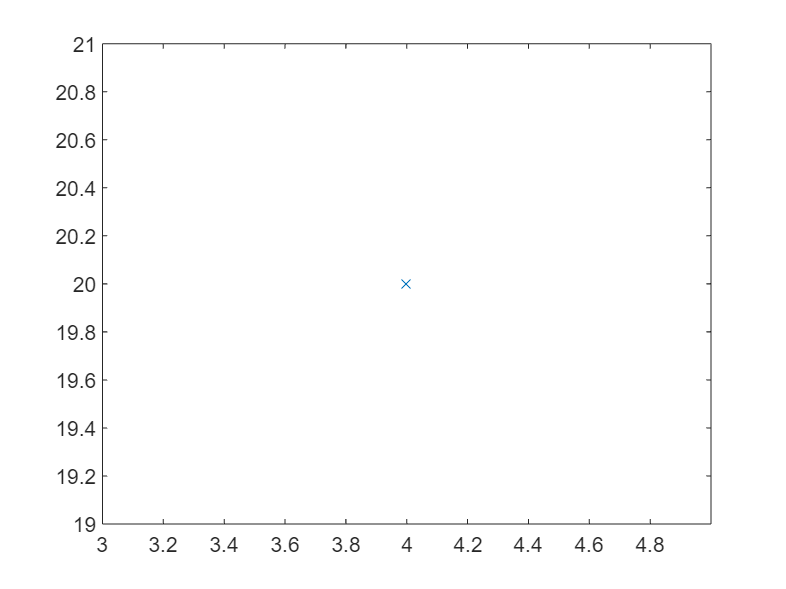

% Wie ist diese Matrixgleichung zu interpretieren?
% Was ist x, was t und was a? -> Verbindung zur Geschwindigkeitsfunktion
% Ist A die Koeffizientenmatrix?
plot(t, y, 'x');
hold on;

% Interpolation mittels polyfit-Funktion in MatLab
% Interpolation mittels eines LGS für zwei Punkte
% Approximation?
koeffLin = polyfit(t, y, 1);

disp (koeffLin);

    7.7545  -11.0181



### 2)

Berechnen Sie $x$ aus den gemessenen Werten, verwenden Sie zunächst `inv` zum invertieren der Matrix. Warum ist das invertieren mit `inv` nicht bei allen Wertepaaren möglich?

% Bildung eines Inversen nur möglich, wenn quadratische Matrix (gleich viele Zeilen
% wie Spalten), seine Determinate != 0 und alle seine Zeilen linear
% Unabhängig sind (voller Rang) -> eindeutige Inverse
% Das dritte und vierte Wertepaar sind keine quadratischen Matrizen,
% demnach kann das Inverse nicht gebildet werden.
if isequal(size(A, 1), size(A, 2)) && det(A) ~= 0
    disp("Det:" + det(A));
    invertA = inv(A);
    x1 = invertA * y;
    disp(x1);
else
    disp("Matrix ist nicht quadratisch oder die Determinante gleicht 0!");
end

Matrix ist nicht quadratisch oder die Determinante gleicht 0!


### 3)

Verwenden sie nun `pinv` oder den `\`-Operator. Unter welchen Umständen können diese ein Ergebnis liefern? Welche Besonderheiten weisen die Wertepaare bzgl. der Lösbarkeit des Gleichungssystems auf? Welche Konsequenzen hat dies für die Berechenbarkeit bzw. Bestimmtheit von $x$?

Recherchieren Sie, wie sie mithilfe des Rangs (`rank`) und der Determinante (`det`) einer Matrix die Lösbarkeit beurteilen können.

% Sind die Ränge einer Koeffizientenmatrix und ihrer erweiterten Gleichung
% nicht identisch, gibt es keine Lösung. 
% Sind sie gleich und auch gleich der Anzahl an Variablen n, so gibt es eine Lsg. 
% Ist n größer als die Ränge, so gibt es unendlich viele Lsg.
% (Haben wir eine erweiterte Koeff.-Matrix benutzt?!)
pinvertA = pinv(A);
x2 = pinvertA * y;
disp(x2);

    4.7059
    1.1765



if isequal(size(A, 1), size(A, 2)) && det(A) ~= 0
    x3 = A \ y;
    disp(x3);
else
    disp("Matrix ist nicht quadratisch oder die Determinante gleicht 0!");
end

Matrix ist nicht quadratisch oder die Determinante gleicht 0!


### 4)

Plotten Sie in die Grafik aus **1)** zusätzlich den Verlauf der Funktion $y(t)$ für den in **2)** berechneten Vektor $x$ im Bereich $t \in \left[ 0; 10 \right]$.

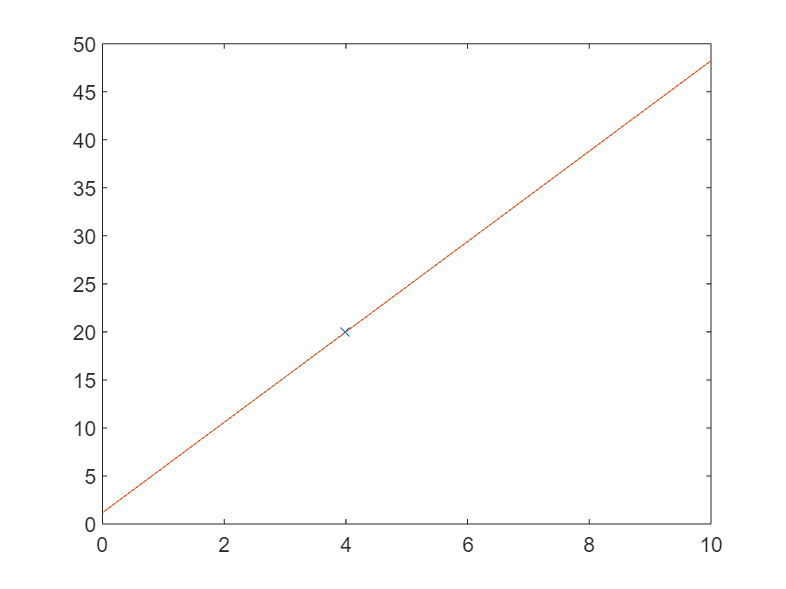

t_t = 0:10;
y = x2(1,1) * t_t + x2(2,1);
plot(t_t, y);
hold off;

Es wird nun eine gleichmäßig beschleunigte Bewegung - eine Verallgemeinerung der gleichförmigen Bewegung - betrachtet:


$$y(t) = \frac{1}{2}a_0 \cdot t^2 + v_0 \cdot t + x_0$$


Das zugehörige Gleichungssystem für $n$ Wertepaare entspricht dann:


$$\begin{array}{c}
y & = & A & \cdot & x \\
\\
\left\lbrack \matrix{
y_1 \cr
y_2 \cr
\vdots \cr
y_n \cr
}\right\rbrack
& = &
\left\lbrack \matrix{
(t_1)^2 & (t_1)^1 & (t_1)^0 \cr
(t_2)^2 & (t_2)^1 & (t_2)^0 \cr
\vdots & \vdots \cr
(t_n)^2 & (t_n)^1 & (t_n)^0 \cr
}\right\rbrack
& \cdot &
\left\lbrack \matrix{
a_0 \cr
v_0 \cr
s_0 \cr
}\right\rbrack
\end{array}$$


Es stehen wieder ähnliche Wertepaare zur Verfügung:

values_a = [0 10; 4 20; 5 25; 10 30];
t_a = values_a(:,1);
y_a = values_a(:,2);

Anstatt die Matrix wie zuvor aus den Spalten zusammenzusetzten, kann sie für den allgemeinen Fall (für Koeffizienten steigender Grade $t^3, t^4, \dots$) aus den letzten 3 Spalten einer Vandermonde-Matrix extrahiert werden:

A_a = vander(t_a);
A_a = A_a(:, end-3+1:end)

A_a =      0     0     1
    16     4     1
    25     5     1
   100    10     1


### 5)

Plotten Sie auch diese Werte in eine neue Grafik mit x-Markern.

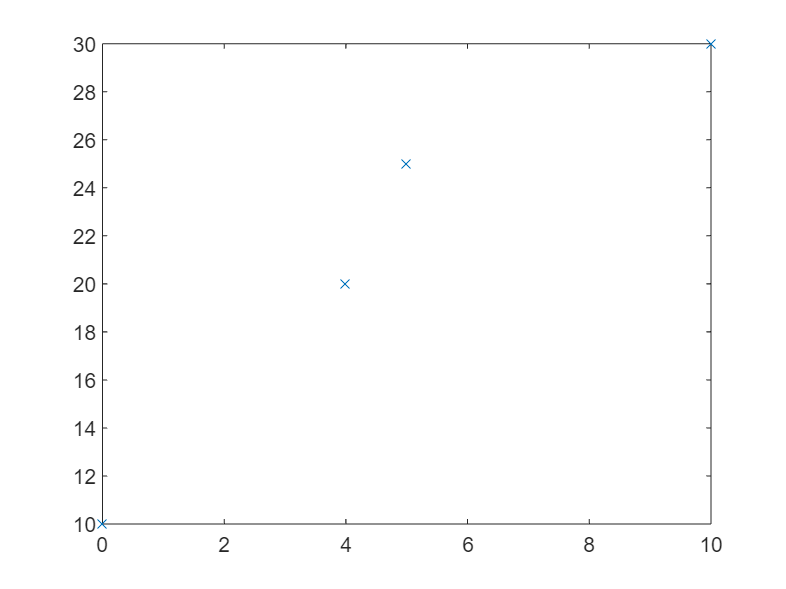

plot(t_a, y_a, 'x');
hold on;

### 6)

Berechnen Sie wieder den Vektor $x$.

*Tipp: Benennen Sie die Variable *`x_a`*, um sie nicht mit den Variablen aus dem ersten Aufgabenteil zu vertauschen.*

x_a = A_a \ y_a;
        disp(x_a);

   -0.1458
    3.4868
    9.8270



if isequal(size(A, 1), size(A, 2))
    if  ~isequal(det(A), 0)
        x_a = A_a \ y_a;
        disp(x_a);
    else
        disp("Die Determinante gleicht 0!");
        x_a = pinv(A_a) * y_a;
        disp(x_a);
    end
else
    disp("Matrix ist nicht quadratisch!");
    x_a = pinv(A_a) * y_a;
    disp(x_a);
end

Die Determinante gleicht 0!


   -0.1458
    3.4868
    9.8270



% Warum funktioniert pinv hier und \ nicht?

### 7)

Wie und warum unterscheiden sich das Ergebnisse insbesondere für die Wertepaare, die bereits bei der gleichförmigen Bewegung zur Auswahl standen?

% Dadurch dass mehr Wertepaare betrachtet werden, wirkt sich auch die
% Invertierung anders aus (?) -> es gibt so keinen Unterschied
% Wir müssen bei nicht quatrischen Matrizen pinv verwenden, um einen x-Wert
% zu erhalten. Somit kann es zu Abweichungen kommen. (?)

% beschleunigte Bewegung benötigt mehr Wertepaare (drei) um die 3 Größen
% a0, v0 und s0 zu berechnen -> es entsteht eine Funktion 2. Grades
% gleichförmige Bewegung benötigt nur zwei Wertepaare um die 2 Größen v0 und
% s0 zu berechnen -> es entsteht einen Funktion 1. Grades

### 8)

Plotten Sie in die Grafik aus **5)** zusätzlich den Verlauf der Funktion $y(t)$ für den in **6)** berechneten Vektor $x$ im Bereich $t \in \left[ 0; 10 \right]$.

*Tipp: Wenn Sie den Plot in ****4)**** geschickt umgesetzt haben, brauchen Sie nur den Variablennamen von *$x$ *zu ändern.*

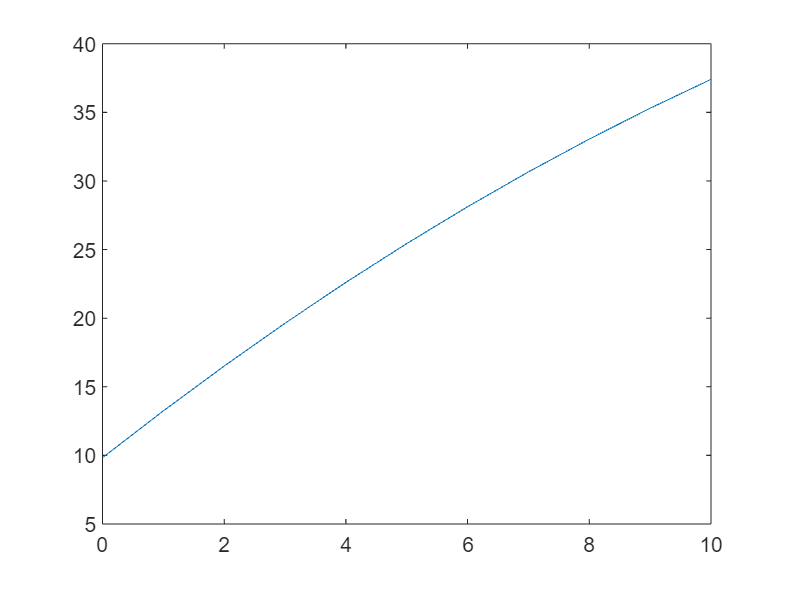

y_a_t = 0.5 * x_a(1,1) .* (t_t.*t_t) + x_a(2,1) .* t_t + x_a(3,1);
% plot liegt nicht auf den Punkten mit faktor 0.5, ohne liegt er drauf
plot(t_t, y_a_t);
hold off;